## **Driver test program to check Clothoids library**

**Test Intersection**

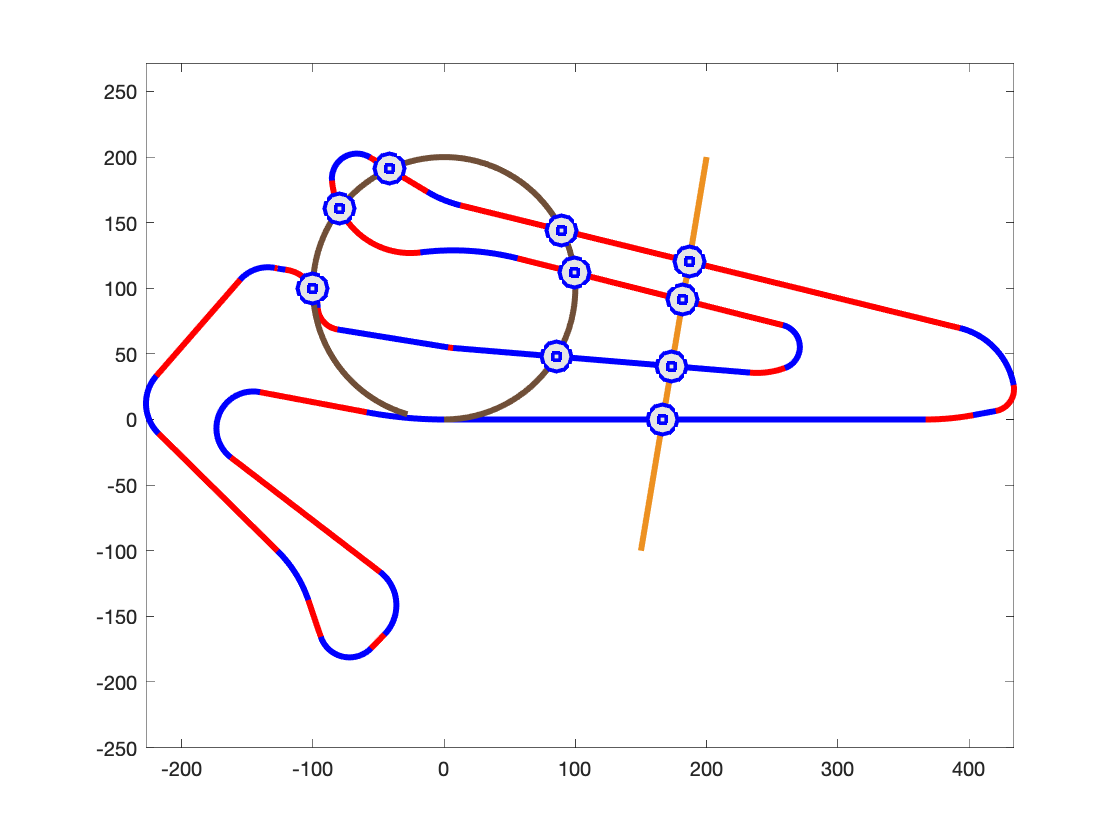

close all;

x0     = 0;
y0     = 0;
theta0 = 0;

S = ClothoidList();

addseg  = @(l,c) S.push_back( c, 0, l );
addseg1 = @(l) S.push_back( 0, 0, l );

S.push_back( x0, y0, theta0, 0, 0, 366.933546 ); % 1
addseg( 36.395335, 0.005014);  % 2
addseg1( 17.508761);           % 3
addseg( 26.719483, 0.058793);  % 4
addseg( 62.995808, 0.018212);  % 5
addseg1( 392.057882);          % 6
addseg( 27.236252, -0.010979); % 7
addseg1( 51.298757);           % 8
addseg( 41.608797, 0.052652);  % 9
addseg( 97.007909, 0.016655);  % 10
addseg( 74.636919, -0.004980); % 11
addseg1( 208.502649);          % 12
addseg( 43.563564, -0.058555); % 13
addseg( 27.095868, -0.015751); % 14
addseg1( 226.951522);          % 15
addseg( 3.891352, -0.020000);  % 16
addseg1( 85.376172);           % 17
addseg( 23.941104, -0.055556); % 18
addseg1( 3.713811);            % 19
addseg( 38.191425, 0.035746);  % 20
addseg( 5.983022, -0.010000);  % 21
addseg1( 2.368430);            % 22
addseg( 29.104257, 0.035714);  % 23
addseg1( 97.139903);           % 24
addseg( 48.274475, 0.031250);  % 25
addseg1( 127.426317);          % 26
addseg( 44.496183, -0.010417); % 27
addseg1( 29.768515);           % 28
addseg( 46.942398, 0.043478);  % 29
addseg1( 14.669384);           % 30
addseg( 54.032989, 0.031250);  % 31
addseg1( 143.257805);          % 32
addseg( 74.854041, -0.035713); % 33
addseg1( 82.764839);           % 34
%addseg( 59.341977, 0.003122);  % 35
S.push_back_G1( x0, y0, theta0); % close curve ...

S.plot();
axis equal

x0 = 150;
y0 = -100;
x1 = 200;
y1 = 200;
L1 = LineSegment( [x0, y0], [x1, y1] );

L1.plot('Color',[0.930000 0.570000 0.130000],'LineWidth',3);

x0     = 0;
y0     = 0;
theta0 = 0;
kappa0 = 0.01;
C1 = CircleArc( x0, y0, theta0, kappa0, 600 );

C1.plot(100,{'Color',[0.440000 0.310000 0.220000],'LineWidth',3});

[s1,s2] = S.intersect( L1 );

XY1 = S.eval( s1 );
XY2 = L1.eval( s2 );

if length(s1) > 0
 plot( XY1(1,:), XY1(2,:), 'o', ...
      'LineWidth',2,...
      'MarkerSize',15,...
      'MarkerEdgeColor','blue',...
      'MarkerFaceColor',[0.9,0.9,0.9] );
end

if length(s2) > 0
  plot( XY2(1,:), XY2(2,:), 's', ...
      'LineWidth',2,...
      'MarkerSize',5,...
      'MarkerEdgeColor','b',...
      'MarkerFaceColor',[0.9,0.9,0.9]);
end

[s1,s2] = S.intersect( C1 );

XY1 = S.eval( s1 );
XY2 = C1.eval( s2 );

if length(s1) > 0
 plot( XY1(1,:), XY1(2,:),  'o', ...
      'LineWidth',2,...
      'MarkerSize',15,...
      'MarkerEdgeColor','blue',...
      'MarkerFaceColor',[0.9,0.9,0.9] );
end

if length(s2) > 0
  plot( XY2(1,:), XY2(2,:), 's', ...
      'LineWidth',2,...
      'MarkerSize',5,...
      'MarkerEdgeColor','b',...
      'MarkerFaceColor',[0.9,0.9,0.9] );
end